# **genetic Minimal Cut Sets - gMCS**

## Authors: Iñigo Apaolaza, University of Navarra, TECNUN School of Engineering, Spain

## Luis V. Valcarcel, University of Navarra, TECNUN School of Engineering, Spain

## Francisco J. Planes, University of Navarra, TECNUN School of Engineering, Spain

## Reviewer(s): 

## INTRODUCTION

Minimal Cut Sets (MCSs) are minimal sets of reaction knockouts which deprive a network from accomplishing a given metabolic task$$^1$. On the other hand, genetic Minimal Cut Sets (gMCSs) consist of minimal sets of genes whose simultaneous inhibition would render the functioning of a given metabolic task impossible$$ ^2$. Therefore, the concepts of MCSs and gMCSs are equivalent but at different levels: at the reaction level for the former and at the gene level for the latter.

MCSs are not directly converted into feasible knockout strategies at a gene level due to the fact that the Gene-Protein-Reaction (GPR) rules, typically provided in genome-scale metabolic reconstructions, are not one-to-one. Certainly, we can find impractical reaction knockouts because they are catalyzed by enzymes involving several genes, which increase the cost of the intervention. On the other hand, the resulting gene knockout interventions from MCSs may provoke undesired metabolic effects, as we may have reactions (included in a particular MCS) catalyzed by an enzyme that additionally participate in other relevant reactions (not included in the MCS under consideration). This fact is further discussed in Apaolaza et al., 2017 (a)$$ ^2$, (b)$$^3$.

Moreover, state-of-the-art methods which calculate combined gene intervention strategies are based on combinatorial approaches and, as a consequence, are not viable for seeking for high order therapeutic strategies in large metabolic networks. This tutorial aims also to demonstrate that the calculation gMCSs involving a large number of genes is viable with the function provided.

## EQUIPMENT SETUP

## Initialize The Cobra Toolbox and select the solver (~25 sec)

If necessary, initialise the Cobra Toolbox:

initCobraToolbox(false) % false, as we don't want to update



      _____   _____   _____   _____     _____     |
     /  ___| /  _  \ |  _  \ |  _  \   / ___ \    |   COnstraint-Based Reconstruction and Analysis
     | |     | | | | | |_| | | |_| |  | |___| |   |   The COBRA Toolbox - 2018
     | |     | | | | |  _  { |  _  /  |  ___  |   |
     | |___  | |_| | | |_| | | | \ \  | |   | |   |   Documentation:
     \_____| \_____/ |_____/ |_|  \_\ |_|   |_|   |   <a href="http://opencobra.github.io/cobratoolbox">http://opencobra.github.io/cobratoolbox</a>
                                                  | 

 > Checking if git is installed ...  Done.
 > Checking if the repository is tracked using git ...  Done.
 > Checking if curl is installed ...  Done.
 > Checking if remote can be reached ...  Done.
 > Initializing and updating submodules (this may take a while)... Done.
 > Adding all the files of The COBRA Toolbox ...  Done.
 > Define CB map output... set to svg.
 > TranslateSBML is installed and working properly.
 > Configuring solver enviro

Note that the approaches to search for MCS and gMCS problems are based on Mixed Integer Linear Programming (MILP). The solver selected will be Cplex.

changeCobraSolver('ibm_cplex', 'all');


 > IBM ILOG CPLEX interface added to MATLAB path.
 > The solver compatibility is not tested with MATLAB R2017a.
 > Solver for LP problems has been set to ibm_cplex.

 > IBM ILOG CPLEX interface added to MATLAB path.
 > The solver compatibility is not tested with MATLAB R2017a.
 > Solver for MILP problems has been set to ibm_cplex.

 > IBM ILOG CPLEX interface added to MATLAB path.
 > The solver compatibility is not tested with MATLAB R2017a.
 > Solver for QP problems has been set to ibm_cplex.
 > Solver ibm_cplex not supported for problems of type MIQP. No solver set for this problemtype 
 > Solver ibm_cplex not supported for problems of type NLP. Currently used: matlab 


## PROCEDURE

This tutorial will be divided in two different parts. First, a toy example will be used to illustrate the difference between MCSs and gMCSs and, second, gMCSs will be calculated for Recon2.v04 metabolic model$$^4$.

## 1. Toy example (~5 sec)

The toy example under study is presented below:

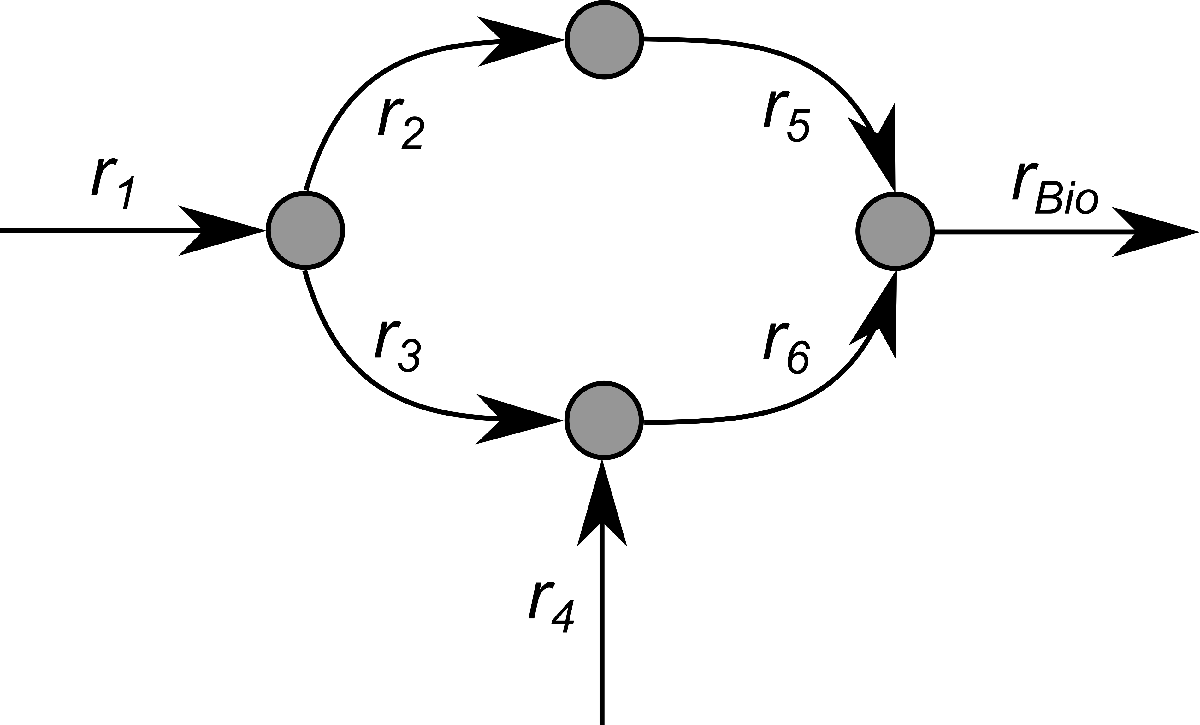

First, we are going to load the MAT-file which contains the metabolic network in the toy example.

load('gMCStoyExample.mat');

As different metabolic models in COBRA format, it contains the following fields: *S*, *ub*, *lb*, *rxns*, *mets*, *genes*, *rules*, *grRules*, *rxnGeneMat *and *c*.

rxns = model.rxns

rxns = 7×1 cell array
    'r1'
    'r2'
    'r3'
    'r4'
    'r5'
    'r6'
    'rBio'

grRules = model.grRules

grRules = 7×1 cell array
    '(g1)'
    '(g2)'
    '(g2) or (g3)'
    '(g4)'
    '(g5) and (g6)'
    '(g5)'
    ''

We can observe that all reactions and genes have a one-to-one relationship except for *r3* and *r5*, which have rules containing 2 different genes and an "or" and an "and" relationship, respectively. On the other hand, *g2* and *g5* take part in two different reactions each. The existence of non-trivial relationships between genes and reactions are the cause of not obtaining the same solutions with MCSs and gMCSs.

We aim to calculate MCSs which will render the biomass production impossible via the function named *calculateMCS()*. Therefore, the desired target metabolic task (represented in the field *c* of the structure) will be the biomass reaction.

model.rxns(logical(model.c))

ans = cell
    'rBio'

We will calculate 10 MCSs and we will set the length of the largest MCS to be calculated to 7 (the number of reactions), in order to calculate all the existing MCSs.

n_MCS = 10;
max_len_MCS = 7;

Now, the different optional arguments of the function must be set, if needed. In this case, we will calculate MCSs involving reactions 1 to 6. The biomass reaction (*rBio*) is omitted since it is the target metabolic task. 

optional_inputs.rxn_set = {'r1'; 'r2'; 'r3'; 'r4'; 'r5'; 'r6'};

The time limit for the calculation of each MCS will be set to 30 seconds.

optional_inputs.timelimit = 30;

Although not shown here, other optional arguments may be set, as detailed in the documentation of the function. 

We will now proceed with the calculation of the MCSs.

[MCSs, MCS_time] = calculateMCS(model, n_MCS, max_len_MCS, optional_inputs);

CPXPARAM_Preprocessing_Fill                      50
CPXPARAM_Preprocessing_Aggregator                50
CPXPARAM_Preprocessing_Dependency                1
CPXPARAM_TimeLimit                               30
CPXPARAM_Preprocessing_Dual                      1
CPXPARAM_Preprocessing_NumPass                   50
CPXPARAM_Output_CloneLog                         -1
CPXPARAM_Preprocessing_CoeffReduce               2
CPXPARAM_Preprocessing_BoundStrength             1
CPXPARAM_MIP_Strategy_HeuristicFreq              1000
CPXPARAM_Preprocessing_Relax                     1
CPXPARAM_Emphasis_MIP                            4
CPXPARAM_Preprocessing_Symmetry                  1
CPXPARAM_MIP_Strategy_RINSHeur                   50
CPXPARAM_MIP_Pool_RelGap                         0.10000000000000001
CPXPARAM_MIP_Limits_Populate                     40

Populate: phase I 
Tried aggregator 2 times.
MIP Presolve eliminated 2 rows and 4 columns.
Aggregator did 3 substitutions.
Reduced MIP has 10 rows, 12 colu

Despite having tried to calculate 10 MCSs, only 6 exist for this Toy Example. The results are shown in the following piece of code:

MCSs{1}

ans = 2×1 cell array
    'r5'
    'r6'

MCSs{2}

ans = 2×1 cell array
    'r1'
    'r6'

MCSs{3}

ans = 2×1 cell array
    'r1'
    'r4'

MCSs{4}

ans = 2×1 cell array
    'r2'
    'r6'

MCSs{5}

ans = 3×1 cell array
    'r2'
    'r3'
    'r4'

MCSs{6}

ans = 3×1 cell array
    'r3'
    'r4'
    'r5'

We now translate these minimal reaction knockout strategies to the gene level following the *grRules*. The following table shows the genetic interventions which must be fulfiilled to accomplish the respective reaction knockouts:

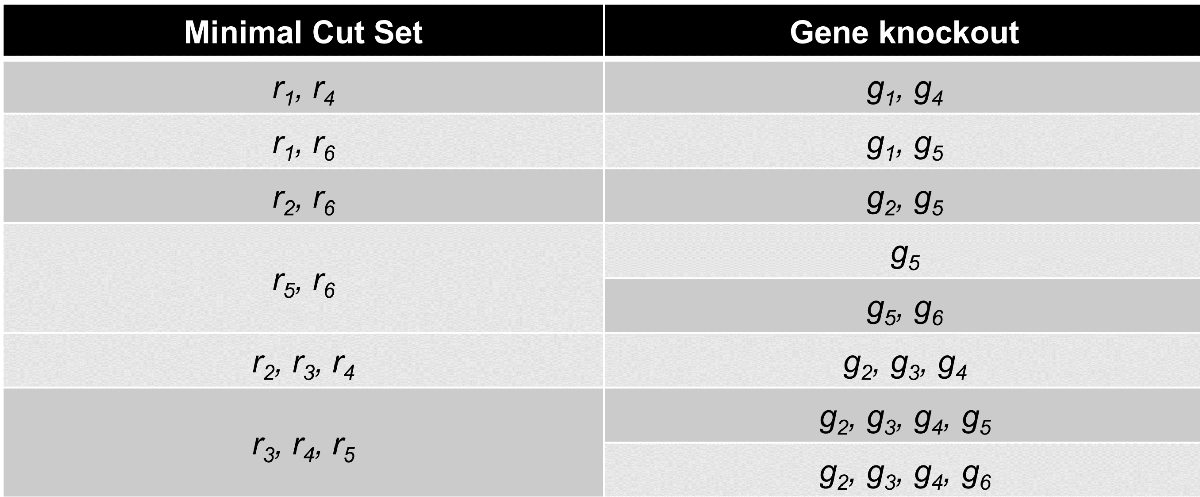

In order to check if the gene knockouts that have to be carried out to perform the inhibition of the found MCSs are minimal, we will calculate gMCSs for the same toy example using the function *calculateGeneMCS()*.

First, we need to define the name of the model to create the gene knockout constraints matrix, *G*. The binary *G *matrix defines for each row the set of blocked reactions arising from the knockout of an irreducible subset of genes. The subset of genes associated with each row in G is interrelated and their simultaneous knockout is required to delete at least one of the reactions in the metabolic network. This matrix may be needed for other calculations. We will name here 'toy_example_gMCS' and again will calculate 10 gMCSs. The function will look for the G matrix in ['G_' model_name '.mat'] (here “G_toy_example_gMCS.mat). If this structure is not available, the function buildGmatrix() is called and the G matrix for the model under consideration generated and saved. In this case, the length of the largest gMCS calculated will be set to 6 (the number of genes).

model_name = 'toy_example_gMCS';
n_gMCS = 10;
max_len_gMCS = 6;

Next, we set the optional inputs. The maximum time for the calculation of each gMCS will be 30 seconds.

optional_inputs.timelimit = 30;

Note that, again, some more optional inputs may be set, as detailed in the documentation of the function. However, they are not needed for the calculation of the problem presented in this tutorial.

We will now proceed with the calculation of the gMCSs.

[gMCSs, gMCS_time] = calculateGeneMCS(model_name, model, n_gMCS, max_len_gMCS, optional_inputs);


G MATRIX - Summary
    'n_rxns_0_genes'     [1]
    'n_rxns_1_gene'      [4]
    'n_rxns_only_or'     [1]
    'n_rxns_only_and'    [1]
    'n_rxns_or_and'      [0]
    'n_rxns_total'       [7]
G MATRIX - STEP 1
G MATRIX - STEP 2
G MATRIX - STEP 3
G MATRIX - STEP 4

G MATRIX - Delete Repeats
G MATRIX - Check Relations
The G Matrix has been successfully calculated
CPXPARAM_Preprocessing_Fill                      50
CPXPARAM_Preprocessing_Aggregator                50
CPXPARAM_Preprocessing_Dependency                1
CPXPARAM_TimeLimit                               30
CPXPARAM_Preprocessing_Dual                      1
CPXPARAM_Preprocessing_NumPass                   50
CPXPARAM_Output_CloneLog                         -1
CPXPARAM_Preprocessing_CoeffReduce               2
CPXPARAM_Preprocessing_BoundStrength             1
CPXPARAM_MIP_Strategy_HeuristicFreq              1000
CPXPARAM_Preprocessing_Relax                     1
CPXPARAM_Emphasis_MIP                            4
CPXPARAM_Prepr

In the same way as with MCSs, 3 gMCSs have been calculated in total.

gMCSs{1}

ans = cell
    'g5'

gMCSs{2}

ans = 2×1 cell array
    'g1'
    'g4'

gMCSs{3}

ans = 3×1 cell array
    'g2'
    'g3'
    'g4'

As shown in the previous table, calculating MCSs would result in 8 different genetic intervention strategies even when, as we have just demonstrated, only 3 minimal genetic interventions exist. Moving on to gMCSs seems, therefore, a more efficient strategy to calculate minimal gene knockout strategies.

## 2. gMCSs in large metabolic networks (20 min ~ 1 hour)

The algorithm presented in this tutorial is able to calculate intervention strategies in large metabolic networks. In addition, it is sufficiently flexible to calculate gMCSs involving a particular gene knockout. Interesting results regarding this issue can be found in Apaolaza et al., 2017(a)$$ ^2$.

We are now going to calculate 6 gMCSs for the human metabolic model Recon2.v04$$^4$ involving gene RRM1 (Entrez ID: 6240). To do so, the folllowing piece of code has to be executed.

First, we are going to load the metabolic model.

global CBTDIR
load([CBTDIR filesep 'test' filesep 'models' filesep 'mat' filesep 'Recon2.v04.mat']);

Next, in the same way as in the toy example, we will proceed to set the name of the model ('Recon2'), the number of gMCSs to be calculated (6), the length of the largest gMCS we want to calculate (10) and the optional input variables. Regarding the latter, the maximum time for the calculation of gMCSs will be set to 2 minutes (120 seconds), the KO will be '6240', namely the Entrez ID of RRM1. In this case, we will also have to set the  "separate_transcript" field to '.', because, if we do not, the calculation of gMCSs will be done at the transcript level as a consequence of the usage of the aforementioned character in Recon2.v04 to differentiate the transcripts of the same gene.

model_name = 'Recon2';
n_gMCS = 6;
max_len_gMCS = 10;
optional_inputs.KO = '6240';
optional_inputs.separate_transcript = '.';
optional_inputs.timelimit = 2*60;

Finally, we will calculate the gMCSs. Turning the parallel pool on is recommended if the G matrix has not been calculated yet.

% parpool;
[gMCSs, gMCS_time] = calculateGeneMCS(model_name, modelR204, n_gMCS, max_len_gMCS, optional_inputs);


G MATRIX - Summary
    'n_rxns_0_genes'     [2619]
    'n_rxns_1_gene'      [2917]
    'n_rxns_only_or'     [1426]
    'n_rxns_only_and'    [ 231]
    'n_rxns_or_and'      [ 247]
    'n_rxns_total'       [7440]
G MATRIX - STEP 1
G MATRIX - STEP 2
G MATRIX - STEP 3
Calculating Networks for GPR rules...
156 of 247 rxns
155 of 247 rxns
84 of 247 rxns
83 of 247 rxns
125 of 247 rxns
124 of 247 rxns
42 of 247 rxns
41 of 247 rxns
154 of 247 rxns
153 of 247 rxns
152 of 247 rxns
151 of 247 rxns
150 of 247 rxns
149 of 247 rxns
148 of 247 rxns
147 of 247 rxns
146 of 247 rxns
145 of 247 rxns
144 of 247 rxns
143 of 247 rxns
142 of 247 rxns
141 of 247 rxns
140 of 247 rxns
139 of 247 rxns
138 of 247 rxns
137 of 247 rxns
136 of 247 rxns
135 of 247 rxns
134 of 247 rxns
133 of 247 rxns
132 of 247 rxns
131 of 247 rxns
130 of 247 rxns
129 of 247 rxns
128 of 247 rxns
127 of 247 rxns
126 of 247 rxns
82 of 247 rxns
81 of 247 rxns
80 of 247 rxns
79 of 247 rxns
78 of 247 rxns
77 of 247 rxns
76 of 247 rxns
75 

The results obtained are the following:

gMCSs{1}

ans = 2×1 cell array
    '2987'
    '6240'

gMCSs{2}

ans = 3×1 cell array
    '1716'
    '6240'
    '7296'

gMCSs{3}

ans = 3×1 cell array
    '1716'
    '50484'
    '6240'

gMCSs{4}

ans = 4×1 cell array
    '1633'
    '1635'
    '6240'
    '7296'

gMCSs{5}

ans = 4×1 cell array
    '26289'
    '51727'
    '6240'
    '7296'

gMCSs{6}

ans = 5×1 cell array
    '2766'
    '3251'
    '51292'
    '6240'
    '8833'

6 gMCSs have been calculated involving 2, 3, 3, 4, 4 and 5 genes, respectively. It is important to note that no more gMCSs have been found as a consequence of setting the number of gMCSs to be calculated to 6. If we increase the aforementiones input, more gMCSs involving RRM1 will be calculated. It is important to note that the calculation of a minimal intervention strategy involving 5 genes with an exhaustive combinatorial strategy is actually inviable.

## TIMING

- Equipment Setup: ~25 sec.

- Toy Example: ~5 sec.

- gMCSs in large metabolic networks: ~5 min.

Note that both *calculateMCS()* and *calculateGeneMCS()* functions return MCS_time and gMCS_time, respectively, which contain the timing for all the solving steps.

## REFERENCES

*1. *von Kamp, A. & Klamt, S. Enumeration of smallest intervention strategies in genome-scale metabolic networks. *PLoS computational biology*, *10*(1), e1003378 (2014).

*2. *Apaolaza, I., *et al*. An in-silico approach to predict and exploit synthetic lethality in cancer metabolism. *Nature Communications*, *8*(1), 459 (2017 (a)). 

*3. *Apaolaza, I., José-Eneriz, E. S., Agirre, X., Prósper, F. & Planes, F. J. COBRA methods and metabolic drug targets in cancer. *Molecular & Cellular Oncology*, (just-accepted), 00-00 (2017 (b)).

*4. *Thiele, I., *et al*. A community-driven global reconstruction of human metabolism. *Nature biotechnology*, *31*(5), 419-425 (2013). 